% Hypertension Demonstration - Arteriolosclerosis
% This script demonstrates hypertension by increasing systemic resistance (Rs)
% Target: 150/105 mmHg blood pressure

clear all
close all
clc

fprintf('=== HYPERTENSION DEMONSTRATION ===\n');

=== HYPERTENSION DEMONSTRATION ===


fprintf('Simulating arteriolosclerosis by increasing systemic resistance\n\n');

Simulating arteriolosclerosis by increasing systemic resistance




% Set up parameters with INCREASED systemic resistance
global T TS TMAX QMAX Rs Csa dt;
T = 0.0125;        % Duration of heartbeat (minutes) --> 80 beats/min
TS = 0.4*T;        % Duration of systole (minutes)
TMAX = 0.16*T;     % Time at which flow is max (minutes)
QMAX = 28;         % Max flow through aortic valve (liters/minute)
Rs = 25.0;         % INCREASED systemic resistance (mmHg/(liter/minute))
                   % Normal = 17.86, Hypertensive = 25.0
Csa = 0.0015;      % Systemic arterial compliance (normal value)
dt = 0.01*T;       % Time step duration (minutes)
klokmax = ceil(16*T/dt); % Total number of timesteps
Psa = 80;          % Starting (diastolic) value of arterial pressure (mmHg)

% Initialize arrays to store data for plotting
t_plot = zeros(1,klokmax);
QAo_plot = zeros(1,klokmax);
Psa_plot = zeros(1,klokmax);

% Run simulation
for klok = 1:klokmax
    t = klok*dt;
    QAo = QAo_now(t);
    Psa = Psa_new(Psa, QAo);
    t_plot(klok) = t;
    QAo_plot(klok) = QAo;
    Psa_plot(klok) = Psa;
end

% Calculate final values from last 4 cycles
cycles_to_use = 4;
cycle_length = round(T/dt);
start_idx = klokmax - cycles_to_use * cycle_length + 1;
pressure_data = Psa_plot(start_idx:end);
systolic = max(pressure_data);
diastolic = min(pressure_data);
cardiac_output = mean(QAo_plot(start_idx:end));

% Display results
fprintf('=== HYPERTENSION SIMULATION RESULTS ===\n');

=== HYPERTENSION SIMULATION RESULTS ===


fprintf('Parameter Changed: Systemic Resistance (Rs)\n');

Parameter Changed: Systemic Resistance (Rs)


fprintf('Normal Rs: 17.86 mmHg/(L/min)\n');

Normal Rs: 17.86 mmHg/(L/min)


fprintf('Hypertensive Rs: %.1f mmHg/(L/min)\n', Rs);

Hypertensive Rs: 25.0 mmHg/(L/min)


fprintf('Increase: %.1f%%\n', ((Rs - 17.86)/17.86)*100);

Increase: 40.0%


fprintf('\nBlood Pressure Results:\n');


Blood Pressure Results:


fprintf('Systolic Pressure: %.1f mmHg\n', systolic);

Systolic Pressure: 154.5 mmHg


fprintf('Diastolic Pressure: %.1f mmHg\n', diastolic);

Diastolic Pressure: 124.2 mmHg


fprintf('Cardiac Output: %.2f L/min\n', cardiac_output);

Cardiac Output: 5.60 L/min


fprintf('Target: 150/105 mmHg\n');

Target: 150/105 mmHg


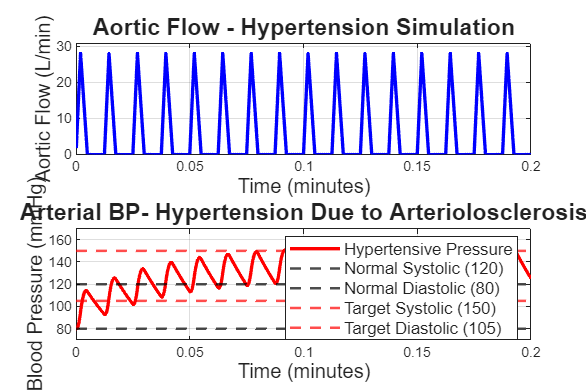


% Create clean, simple plot
figure('color','white', 'Position', [50, 50, 1200, 800])

% Upper subplot: Aortic Flow
subplot(2,1,1)
plot(t_plot, QAo_plot, 'b-', 'linewidth', 2)
xlabel('Time (minutes)', 'FontSize', 12)
ylabel('Aortic Flow (L/min)', 'FontSize', 12)
title('Aortic Flow - Hypertension Simulation', 'FontSize', 14)
grid on
axis([0, max(t_plot), 0, max(QAo_plot)*1.1])

% Lower subplot: Arterial Pressure
subplot(2,1,2)
plot(t_plot, Psa_plot, 'r-', 'linewidth', 2)
xlabel('Time (minutes)', 'FontSize', 12)
ylabel('Blood Pressure (mmHg)', 'FontSize', 12)
title('Arterial BP- Hypertension Due to Arteriolosclerosis', 'FontSize', 14)
grid on
axis([0, max(t_plot), 70, 170])

% Add simple reference lines
yline(120, '--k', 'LineWidth', 1.5)
yline(80, '--k', 'LineWidth', 1.5)
yline(150, '--r', 'LineWidth', 1.5)
yline(105, '--r', 'LineWidth', 1.5)

% Add simple legend
legend('Hypertensive Pressure', 'Normal Systolic (120)', 'Normal Diastolic (80)', ...
       'Target Systolic (150)', 'Target Diastolic (105)', ...
       'Location', 'northeast', 'FontSize', 10)


fprintf('\n=== PLOT GENERATED ===\n');


=== PLOT GENERATED ===


fprintf('The plot shows:\n');

The plot shows:


fprintf('- Upper panel: Aortic flow (unchanged)\n');

- Upper panel: Aortic flow (unchanged)


fprintf('- Lower panel: Increased blood pressure due to higher resistance\n');

- Lower panel: Increased blood pressure due to higher resistance


fprintf('- Red lines show hypertensive pressures\n');

- Red lines show hypertensive pressures


fprintf('- Black dashed lines show normal pressures for comparison\n');

- Black dashed lines show normal pressures for comparison
